
% decoder
clc;clear;
YPR=[0 0 0];
XYZ=[0; 0.6173; 0.1-0.77+0.63];
YPR2=[0 0 0];
XYZ2=[0.5173;0.0;0.5-0.77]

XYZ2 =     0.5173
         0
   -0.2700


% Solve Phase Trajectories
ur5=importrobot('ur5_InverseKinematic.urdf');
% show(ur5)

% Vehicle Edge
% Vehicle Floor
Height=0.77;
env = {collisionBox(1.5, 0.5, 0.3) collisionBox(1.5, 0.8, 0.01)};
env{1}.Pose(1:3, end) = [0.75 0.58 0.45-Height];
env{2}.Pose(1:3, end) = [0.75 0 0.28-Height];





Pose1=[eul2rotm(YPR)*eul2rotm([-pi/2 -pi/2 0]) XYZ;0 0 0 1];
Pose2=[eul2rotm(YPR2)*eul2rotm([-pi/2 -pi/2 0]) XYZ2;0 0 0 1];
ik = inverseKinematics('RigidBodyTree',ur5);
% weights = [0.25 0.25 0.25 1 1 1];
weights = [0.25 0.25 0.25 10 10 10];
initialguess = ur5.homeConfiguration;
[configSol1,solnInfo] = ik('EndEffort',Pose1,weights,initialguess);
[configSol,solnInfo] = ik('EndEffort',Pose2,weights,initialguess)

configSol = 1×6 struct array with fields:
    JointName
    JointPosition


solnInfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6232e-09
             ExitFlag: 1
               Status: 'success'



startConfig=[configSol1(1).JointPosition,configSol1(2).JointPosition,...
    configSol1(3).JointPosition,configSol1(4).JointPosition,...
    configSol1(5).JointPosition,configSol1(6).JointPosition];

goalConfig=[configSol(1).JointPosition,configSol(2).JointPosition,...
    configSol(3).JointPosition,configSol(4).JointPosition,...
    configSol(5).JointPosition,configSol(6).JointPosition];


% startConfig=[0 0 0 0 0 0];
rrtPlanner = manipulatorRRT(ur5,env);
% rrtPlanner.MaxIterations=MaxIter;
rrtPlanner.MaxConnectionDistance =0.1;
rrtPlanner.ValidationDistance=0.01;
rrtPlanner.EnableConnectHeuristic=0; 
path = plan(rrtPlanner,startConfig,goalConfig)

path =     1.2427   -0.7824    1.8019   -1.0195    1.2427   -0.0000
    1.1660   -0.7996    1.7497   -1.0238    1.2716    0.0155
    1.1000   -0.7744    1.7323   -1.0260    1.2031    0.0129
    1.0347   -0.7482    1.7146   -1.0258    1.1345    0.0075
    0.9945   -0.7086    1.6642   -1.0239    1.0721   -0.0121
    0.9284   -0.6819    1.6442   -1.0240    1.0053   -0.0199
    0.8655   -0.6543    1.6203   -1.0209    0.9375   -0.0299
    0.8000   -0.6233    1.6017   -1.0174    0.8715   -0.0348
    0.7269   -0.6246    1.5518   -1.0312    0.9031   -0.0660
    0.6651   -0.6042    1.5370   -1.0369    0.8290   -0.0604


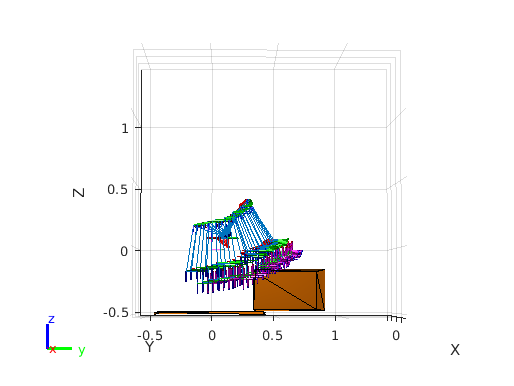

% path = interpolate(rrtPlanner,path,1);

clf
robot=importrobot('ur5_InverseKinematic.urdf');
for i = 1:size(path,1)
    configSol1(1).JointPosition=path(i,1);
    configSol1(2).JointPosition=path(i,2);
    configSol1(3).JointPosition=path(i,3);
    configSol1(4).JointPosition=path(i,4);
    configSol1(5).JointPosition=path(i,5);
    configSol1(6).JointPosition=path(i,6);

    show(robot,configSol1);
    hold on
end
show(env{1})
show(env{2})
hold off

xlim([-0.50 1.50])
ylim([-0.51 1.49])
zlim([-0.48 1.52])
view([88.08 -1.15])